#### **Exercícios - Resolução de sistemas de equações lineares**

**1)** Um problema comum na engenharia elétrica envolve a determinação das correntes e tensões em várias posições em circuitos de resistores. Esses problemas são resolvidos usando-se as regras de Kirchhoff para correntes e tensões. A aplicação dessas regras resulta em um sistema de equações algébricas lineares.

Considere o circuito mostrado abaixo

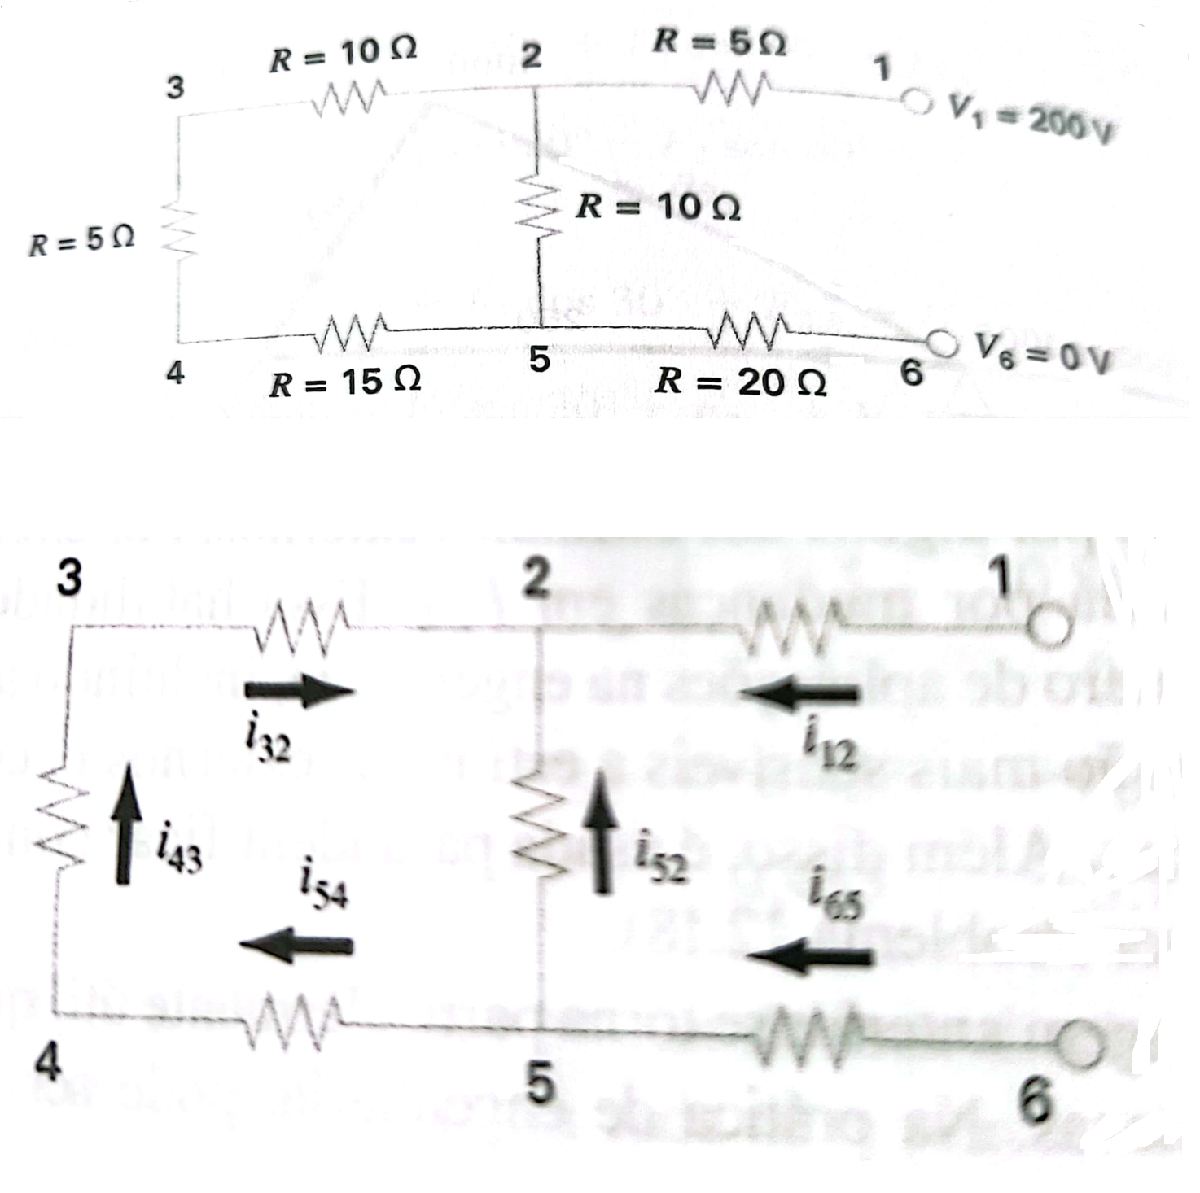

Esse problema se transforma em resolver o seguinte conjunto de seis equações por seis correntes desconhecidas:


$$\begin{cases}
i_{12} + i_{52} + i_{32} = 0\\
i_{65} - i_{52} - i_{54} = 0\\
i_{43} - i_{32} = 0\\
i_{54} - i_{43} = 0\\
-15i_{54}-5i_{43}-10i_{32}+10i_{52}=0\\
-20_{65}-10i_{52}+5i_{12} = 200
\end{cases}$$


a) Resolva este sistema por eliminação de Gauss e Fatoração LU (com estratégia de pivoteamento parcial, lembre-se que o Matlab já faz isso):

%[L,U] = lu(A)
%Ux=y
%Ly=b
%x é o vetor de correntes i = {i12,i52,i32,i65,i54,i43} 

A = [1   1   1  0   0   0;
     0   0  -1  0  -1   1;
     0  -1   0  1   0   0;
     0   0   0 -1   1   0;
     0 -10  10 -5 -15   0;
     5   0 -10  0   0 -20]

A =      1     1     1     0     0     0
     0     0    -1     0    -1     1
     0    -1     0     1     0     0
     0     0     0    -1     1     0
     0   -10    10    -5   -15     0
     5     0   -10     0     0   -20


b = [0; 0; 0; 0; 0; 200]

b =      0
     0
     0
     0
     0
   200


[L,U] = lu(A);
y = L\b

y =   200.0000
         0
  -40.0000
  -10.0000
   -7.2727
  -16.0000


x = U\y

x =     6.1538
   -1.5385
   -4.6154
   -1.5385
   -1.5385
   -6.1538


[L, U, P] = lu(A);
y = L\(P*b) %multiplicar o vetor B pela matriz de permutação

y =   200.0000
         0
  -40.0000
  -10.0000
   -7.2727
  -16.0000


**2)** Uma bomba peristáltica produz um escoamento unitário $Q_{1}$ de um fluido altamente viscoso. Cada seção de tubo tem os mesmos comprimento e diâmetro. Os balanços de massa e energia mecânica podem ser simplificados para se obter os escoamentos em cada tubo. Resolva o sistema de equações a seguir para obter o escoamento de cada corrente. Use o método de Gauss-Jacobi.


$$\begin{cases}
Q_{3} +2 Q_{4} - 2Q_{2} = 0\\
Q_{5} +2 Q_{6} - 2Q_{4} = 0\\
3Q_{7} -2 Q_{6}= 0\\
Q_{1} = Q_{2} + Q_{3}\\
Q_{3} = Q_{4} + Q_{5}\\
Q_{5} = Q_{6} + Q_{7}\\
\end{cases}$$


A = [1 0 0 0 0 0 0;
     0 -2 1 2 0 0 0;
     -1 1 1 0 0 0 0;
     0 0 0 -2 1 2 0;
     0 0 -1 1 1 0 0;
     0 0 0 0 0 -2 3;
      0 0 0 0 -1 1 1];

b = [1; 0; 0; 0; 0; 0; 0];

% critério de linhas para verificar se o método de Jacobi

[m n] = size(A);
for k = 1:n
    s = 0;
    for j = 1:n
        if j ~= k 
            s = s + abs(A(k,j));
        end
    end
    alpha(k) = s/A(k,k);
end    
alpha_max = max(alpha);

% utilizando o método

for i = 1:n
    for j = 1:n
        if i == j
            C(i,j) = 0;
        else
            C(i,j) = -A(i,j)/A(i,i);
        end
    end
    g(i) = b(i)/A(i,i);
end
C, g;

C =          0         0         0         0         0         0         0
         0         0    0.5000    1.0000         0         0         0
    1.0000   -1.0000         0         0         0         0         0
         0         0         0         0    0.5000    1.0000         0
         0         0    1.0000   -1.0000         0         0         0
         0         0         0         0         0         0    1.5000
         0         0         0         0    1.0000   -1.0000         0


% % % % % % 
k = 0;
% x0 = zeros(n,1); %vetor de n zeros

x0 = [2;0.7;]
tol = 0.05;
d = 20;
while(d > tol)
    x = C*x0 + g';
    d = norm(x-x0, inf);
    x0 = x;
    k = k+1;
    xit(k,:) = x0;
    dit(k,:) = d;
end
xit, dit;

xit = 1.0e+308 *

    0.0000         0         0         0         0         0         0
    0.0000         0    0.0000         0         0         0         0
    0.0000    0.0000    0.0000         0    0.0000         0         0
    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000
    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000         0    0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Q=A\b

Q =     1.0000
    0.5059
    0.4941
    0.2588
    0.2353
    0.1412
    0.0941


**3)** Uma treliça é submetida a uma carga de $24 kN$. Usando o seguinte conjunto de equações, determine as dez incógnitas: $AB,BC,AD,BD,CD,DE,CE,A_{x},A_{y},E_{y}$. Utilize o método de Gauss-Seidel.


$$\begin{cases}
A_{x}+AD = 0\\
A_{y} +AB= 0\\
74+BC+\frac{3}{5}BD=0\\
-AB-\frac{4}{5}BD=0\\
-BC+\frac{3}{5}CE=0\\
-24-CD-\frac{4}{5}CE=0\\
-AD +DE-\frac{3}{5}BD =0\\
CD+\frac{4}{5}BD=0\\
-DE-\frac{3}{5}CE=0\\
E_{y}+\frac{4}{5}CE=0
\end{cases}$$


A = [-1  0  0  -4/5  0  0    0   0   0   0;
      0  -1  0    0   0   0  3/5  0   0   0;
      0  0  -1  -3/5  0   1    0   0   0   0;
      0  1  0   3/5   0   0    0   0   0   0;
      0  0  0   4/5   1   0    0   0   0   0;
      0  0  0    0    0  -1  -3/5 0   0   0;
      0  0  0    0   -1   0  -4/5 0   0   0;
      0  0  1    0    0   0    0   1   0   0;
      1  0  0    0    0   0    0   0   1   0;
      0  0  0    0    0   0   4/5 0   0   1];

b = [0; 0; 0; -74; 0; 0; 24; 0; 0; 0];

% Critério de Sassenfeld
n = size(A,1);
B = zeros(n,1);
for i = 1:n
    soma1 = sum(abs(A(i,1:i-1)) .* B(1:i-1)');
    soma2 = sum(abs(A(i,i+1:n)));
    B(i) = (soma1 + soma2) / abs(A(i,i));
end
disp('Coeficientes de Sassenfeld:');

Coeficientes de Sassenfeld:


disp(B);

   0.800000000000000
   0.600000000000000
   1.600000000000000
   1.000000000000000
   0.800000000000000
   0.600000000000000
   1.000000000000000
   1.600000000000000
   0.800000000000000
   0.800000000000000




% Método de Gauss-Seidel
x0 = A\b;                   
x0([1 5 8 9]) = [100; 30; -700; -1]; % Garantir vetor coluna

tol = 0.05;
max_iter = 15;
k = 0;
erro = inf;

% Pré-alocação CORRETA (10 variáveis x 15 iterações)
xit = zeros(10, max_iter);  % Matriz 10x15
dit = zeros(1, max_iter);   % Vetor 1x15

while erro > tol && k < max_iter
    x_antigo = x0; 
    
    % Atualizações sequenciais (vetor coluna)
    x0(1) = (b(1) - A(1,2:end)*x0(2:end)) / A(1,1);
    x0(2) = (b(2) - A(2,[1,3:end])*x0([1,3:end])) / A(2,2);
    x0(3) = (b(3) - A(3,[1:2,4:end])*x0([1:2,4:end])) / A(3,3);
    x0(4) = (b(4) - A(4,[1:3,5:end])*x0([1:3,5:end])) / A(4,4);
    x0(5) = (b(5) - A(5,[1:4,6:end])*x0([1:4,6:end])) / A(5,5);
    x0(6) = (b(6) - A(6,[1:5,7:end])*x0([1:5,7:end])) / A(6,6);
    x0(7) = (b(7) - A(7,[1:6,8:end])*x0([1:6,8:end])) / A(7,7);
    x0(8) = (b(8) - A(8,1:8)*x0(1:8)) / A(8,8);       % Correção aqui
    x0(9) = (b(9) - A(9,1:9)*x0(1:9)) / A(9,9);       % Correção aqui
    x0(10) = (b(10) - A(10,1:10)*x0(1:10)) / A(10,10); % Correção aqui
    
    % Cálculo do erro
    erro = norm(x0 - x_antigo, inf);
    k = k + 1;
    
    % Atribuição CORRETA (dimensões compatíveis)
    xit(:,k) = x0;  % Coluna k recebe vetor coluna x0
    dit(k) = erro;   % Elemento k recebe escalar
end

% Exibição dos resultados
fprintf('\nSolução após %d iterações (Erro = %.4f):\n', k, erro);


Solução após 15 iterações (Erro = 1326.0000):


disp(array2table(x0', 'VariableNames', {'AB','BC','AD','BD','CD','DE','CE','Ax','Ay','Ey'}));

           AB           BC     AD           BD                   CD           DE           CE            Ax            Ay            Ey
    ________________    ___    __    _________________    ________________    __    _________________    ___    _________________    __

    37.3333333333333    -46    74    -46.6666666666667    37.3333333333333    46    -76.6666666666667    626    -36.3333333333333    0 



**4)** Resolva eficientemente o sistema:


$$\begin{cases}
8x_{1}-2x_{2}-x_{3}=5\\
-2x_{1}+9x_{2}-4x_{3}-x_{4}=2\\
-x_{1}-3x_{2}+7x_{3}-x_{4}-2x_{5}=0\\
-4x_{2}-2x_{3}+12x_{4}-5x_{5}=1\\
-7x_{3}-3x_{4}+15x_{5}=5\\
\end{cases}$$


A = [ 8 -2 -1  0  0;
     -2  9 -4 -1  0;
     -1 -3  7 -1 -2;
     0  -4 -2 12 -5;
     0   0 -7 -3 15];
b = [5; 2; 0; 1; 5];
n = size(A, 1);

% Critério de Sassenfeld
B = zeros(n, 1); % Inicializa o vetor B
for i = 1:n
    sum_b1 = 0;
    sum_b2 = 0;
    for j = 1:i-1
        sum_b1 = sum_b1 + abs(A(i, j)) * B(j);
    end
    for j = i+1:n
        sum_b2 = sum_b2 + abs(A(i, j));
    end
    B(i) = (sum_b1 + sum_b2) / abs(A(i, i));
end

fprintf('Coeficientes de Sassenfeld:\n');

Coeficientes de Sassenfeld:


for i = 1:n
    fprintf('B(%d) = %.4f\n', i, B(i));
end

B(1) = 0.3750
B(2) = 0.6389
B(3) = 0.7560
B(4) = 0.7556
B(5) = 0.5039


% Método de Gauss-Seidel
x0 = zeros(1, n);
tol = 0.05;
k = 0;
d = 10;

while d > tol
    x = x0; % Inicializa x com os valores anteriores
    for i = 1:n
        soma1 = 0;
        soma2 = 0;
        for j = 1:i-1
            soma1 = soma1 + A(i, j) * x(j);
        end
        for j = i+1:n
            soma2 = soma2 + A(i, j) * x0(j);
        end
        x(i) = (b(i) - soma1 - soma2) / A(i, i);
    end
    d = norm(x - x0, inf);
    x0 = x;
    k = k + 1;
end

fprintf('\nSolução encontrada após %d iterações:\n', k);


Solução encontrada após 6 iterações:


disp(x0);

   0.952347874407265   0.919195242005090   0.917833685651455   0.924554867564482   0.946566693483575

